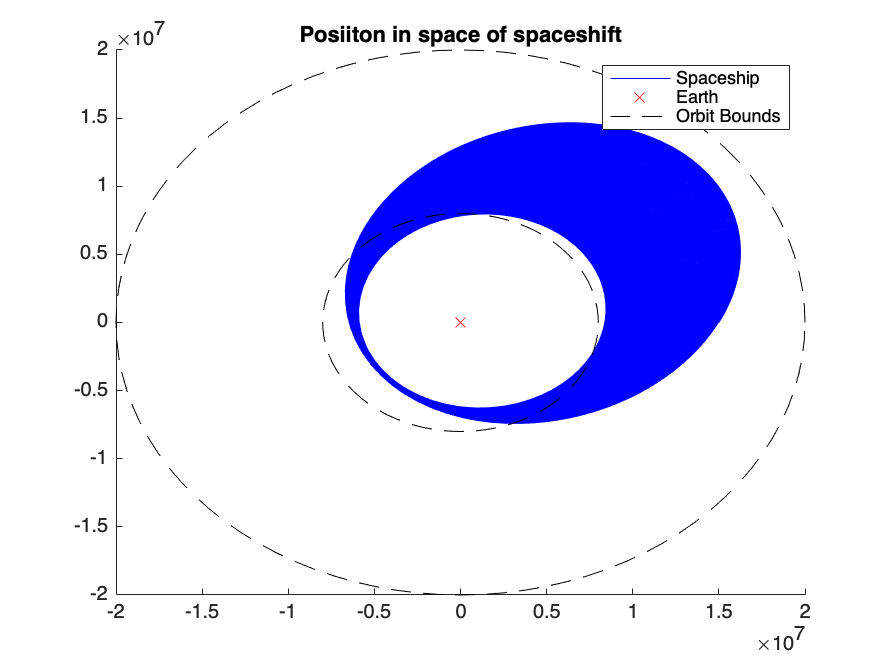

%initial poistion and veolcity 
x0 = [15*10^6;0];
v0 =[2*10^3; 4*10^3];

%%earth orbit 
%x0 = [-15.0*10^6;0];
%v0 =[0; -5*10^3];

%moon orbit 
%x0 = [2*10^8;-3.4*10^8];
%v0 =[5*10^2; 9*10^2];

%creating a time vector with time step 100 seconds to facilitate
%computation
t0 = 0; 
tf = 2358730;
time = 0:100:tf;
                                 
%other solvers 
%[t,y] = ode45(@spaceship_system, [0,tf], [x0;v0]);
%[t1, y1] = kutta(@spaceship_system, [0,tf], [x0;v0]);
%[t2, y2] = ode45(@spaceship_system, [0,tf], [x0;v0]);

%using my heun solver to solve the ODEs
[t,y] = kutta(@spaceship_system, time, [x0;v0]);
t=t';y=y'; %transposing because ode45 and our methods output differently oriented vectors
moon_pos = moon_position(time);
%plotting position in 2d

%plot(moon_pos(1, :), moon_pos(2, :)); 


%plotting solution of ODE around the earht with its orbit bounds (exercise
%7)
figure()
hold on;
xlim auto; ylim auto
plot(y(:, 1),y( :, 2), 'Color', 'blue'); %spaceship posiiton 
plot(0, 0, 'xr')%earth
[xmin, ymin] = circle(0,0, 8*10^6); %orbit bounds lower
[xmax, ymax] = circle(0,0, 20*10^6);%orbit bounds upper
plot(xmin, ymin, '--k', xmax, ymax, '--k') %plotting bounds
title("Posiiton in space of spaceshift")
legend('Spaceship', 'Earth',  'Orbit Bounds')
hold off;

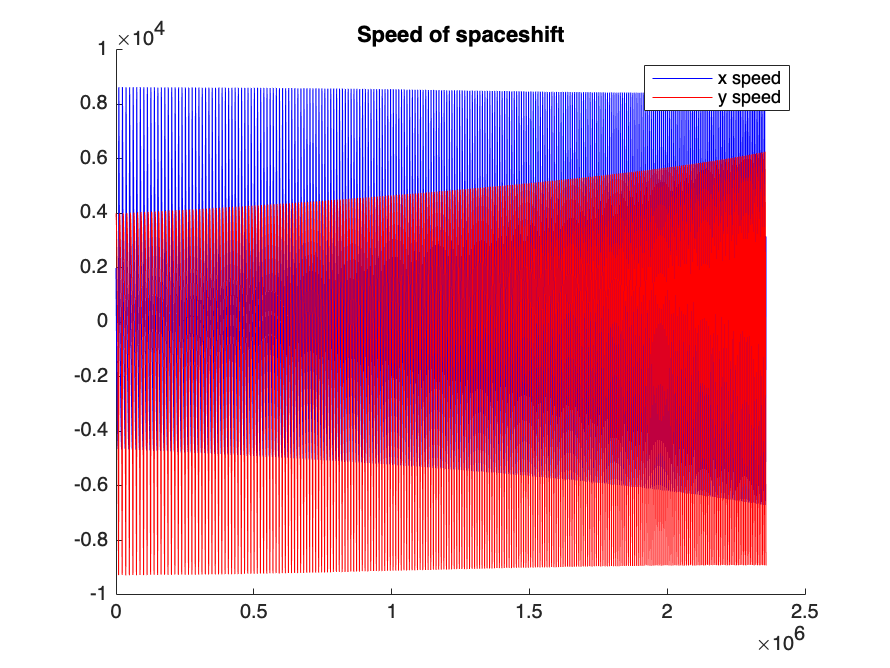


%plotting speeds for studying effect of thrust (ex 7)
figure()
hold on 
plot(t, y(:, 3), 'Color', 'blue')%plotting x speed
plot(t, y(:, 4), 'Color', 'red')%plotting y speed
title("Speed of spaceshift")
legend('x speed', 'y speed')
hold off